%计算考虑化学作用后的三锁体系
clear all
syms e r o ;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
l=4.5;


%计算锁死所占成分
fun1 = @(x1,x2,x3) P(x3).^2.*P(x2-x3).^2.*P(x1-x2).^2.*P(l-x1);
x3max= @(x1,x2) 1*x2;
x2max= @(x1) 1*x1;
V_lock = 4*integral3(fun1,0,l,0,x2max,0,x3max);

%计算开放所占成分
fun2 = @(x1,x2,x3) P(l-x3).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x2).*P(x1-x2);
x3max= @(x1,x2) 1*x2;
x2max= @(x1) 1*x1;
V_open1 = 2*integral3(fun2,0,l,0,x2max,0,x3max);
fun3 = @(x1,x2,x3) P(l-x2).*P(x3).*P(x2-x3) ...
        .*P(x1-x2).*P(l-x1).*P(x3).*P(x1-x3);
x3max= @(x1,x2) 1*x2;
x2max= @(x1) 1*x1;
V_open2 = 2*integral3(fun3,0,l,0,x2max,0,x3max); 
V_open=V_open1 + V_open2;
P_lock = V_lock/(V_lock + V_open) %计算锁死所占比例

P_lock = 0.4633

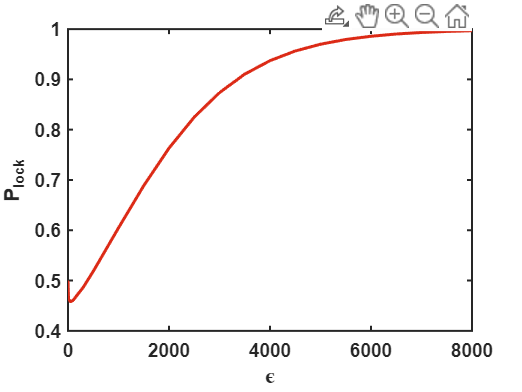





%画出锁死概率随l的变化
e=[0 10 50 100 300 500 1000 1500 2000 ...
    2500 3000 3500 4000 ...
    4500 5000 5500 6000 ...
    6500 7000 7500 8000];
Plock=[0.5 0.4633 0.4580 0.4607 0.4863 0.5184 0.6047 0.6887 0.7632 ...
    0.8250 0.8737 0.9104 0.9372 ...
    0.9564 0.9699 0.9793 0.9857 ...
    0.9902 0.9932 0.9953 0.9967];
plot(e, Plock,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)


set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('\epsilon','FontName','arial','FontWeight','bold'); 
ylabel('P_{lock}','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=10;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end

